# Moments

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

A moment of force is a measure of the amount and direction of rotation imparted to a system by a particular force. When describing a static system, it is required to track the balance of all moments. Vectors provide a helpful tool for such analysis.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Moment

The moment measures the rotational force in a system. Moment can also be called torque or moment of force. The radius at which the force acts is called the moment arm. Levers apply the principle of moment to make a small amount of force applied at one end of a moment arm impart significantly more force at the other end.

### Moment with respect to a point

#### 
$$\vec{M} = \vec{r}\times \vec{F}$$


  **Try.** What is the moment about point $C$ when a constant downward force of 15 Newtons is applied at point A and a variable force is applied at point B with arms $L_1 = 1.1 \text{ m}$ and $L_2 = 0.1 \text{ m}$?

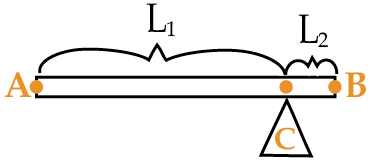 

L_1 = 1.1; % m
L_2 = 0.1; % m
F_A = 15;  % N

Let's define a coordinate system where up is $+z$, right is $+y$ and out towards us is $+x$.  

r_1 = [0 L_1 0];
FAvec = [0 0 -F_A];

Then the moment about C caused by the force at A is:

M_AC = cross(r_1,FAvec)

**Note: **In 2D beam analysis, a positive moment is said to be in a counter-clockwise direction because of the rotation it will impart. A negative moment is said to be in a clockwise direction. 

 **Reflect**. What is the direction (positive/counter-clockwise or negative/clockwise) of the moment `M_AC` about which axis?

checkDir([-1 0 0])

Now compute the moment at C caused by the force you chose at B:

F_B = 0; % N
r_2 = [0 -L_2 0];
FBvec = [0 0 -F_B];
M_BC = cross(r_2,FBvec)

 **Reflect**. What value of `FBvec` results in a static equilibrium for this system? Why? 

Run this section to check whether the values you have chosen for `L_1`, `L_2`, `F_A`, and `F_B` balance.

checkStaticF_B(FAvec,r_1,FBvec,r_2)

### Moment along an axis

#### 
$$M_i = (\vec{r}\times \vec{F})\cdot \vec{e}_i$$


While the moment with respect to a point is a vector perpendicular to the force and the moment arm, the moment along an axis is a scalar value. The calculation of the moment along an axis requires defining both a point and an axis. The unit vector $\vec{e}_i$ is along the axis and the vector $\vec{r}$ is from a point on the axis to the point of application of the force $\vec{F}$. 

###  **Exercise 1: Calculate the Moment of Force Around an Axis**

In the following figure, the magnitude of $F_B=858 \text{ N}$ and the magnitude of $F_C=462 \text{ N}$. The measured distances are $d_1 = 6 \text{ m}$, $d_2 = 2\text{ m}$, $d_3 = 3\text{ m}$, and $d_4 = 2.5\text{ m}$. Determine the resulting moment of force with respect to an axis parallel to the direction of the $x$-axis around the point $O$. Repeat this calculation to determine the moment of force parallel to the $y$-axis. 

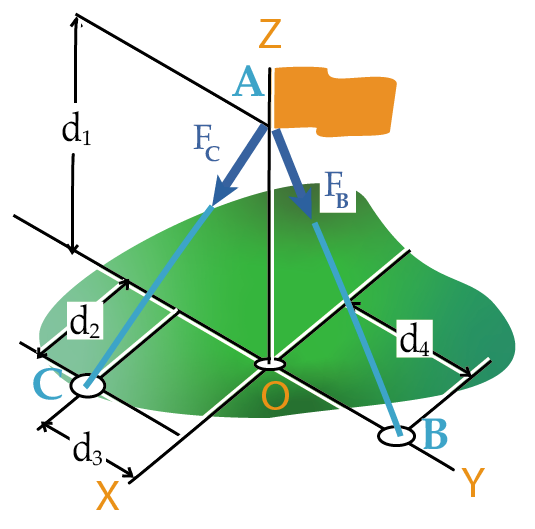

Identify the Cartesian coordinates of each point in the diagram. This is an exercise in reading the diagram, no calculation is required.

O = [0 0 0];
A = nan;
B = nan;
C = nan;
CheckEx1Coords(A,B,C)

Create the unit vectors $u_{AC}$ in the $\vec{AC}$ direction and $u_{AB}$ in the $\vec{AB}$ direction. 

**Hint: **Remember the definitions of unit vectors discussed in [StaticForces.mlx](matlab:open('./StaticForces.mlx')). 

u_AC = nan;
u_AB = nan;

Define the vector forces $\vec{F}_{C}$ and $\vec{F}_B$:

F_C = nan;
F_B = nan;

Define the resultant force:

F_R = nan % N-m

Calculate the moment on the flag pole with respect to the point $O$. You will want to use the command [`cross`](https://www.mathworks.com/help/matlab/ref/cross.html)`.`

r_OA = A-O;
MR = nan % N-m

Calculate the moment with respect to the $x$ and $y$ axes. What do you 

e_x = [1 0 0];
e_y = [0 1 0];

Mx = nan % N-m
My = nan % N-m

 
out1 = CheckEx1(Mx,My,F_C,F_B,r_OA);

  **Reflect**. Given these results for the moment on the flag pole, is it falling over? Why or why not?

###  **Exercise 2: Recalculate the Moment of Force Around a Different Axis**

Now recalculate for the moment with respect to an axis passing through $O$ in the $XY$ plane at an angle of $45^{\circ}$.

M_axis = nan
if ~exist("out1","var") || out1==-1
    disp("Please complete Exercise 1 before attempting Exercise 2.")
else
    CheckEx2(M_axis);
end
 

  **Reflect**. 

- Compare the results of Exercise 1 and Exercise 2. Do they make sense? Why or why not?

- If we choose a different coordinate system to work in, does it change the physics of the problem?

- What does it mean to have a reaction moment (or a reaction force) that acts at zero distance from the point of reference?

###  **Exercise 3: Determine the Maximum Load with Fixed Maximal Tensions**

Three cables come together at a hook $A$ and terminate at points $B$, $C$, and $D$ along the edges of a uniform sheet of material with dimensions provided. Let `w` be the weight of the sheet in Newtons and `g` be the acceleration due to gravity in $\frac{m}{s^2}$.

g = 9.81;    % m/s^2

Determine the maximum mass in kilograms that can be supported in this fashion without exceeding 15kN in any cable.

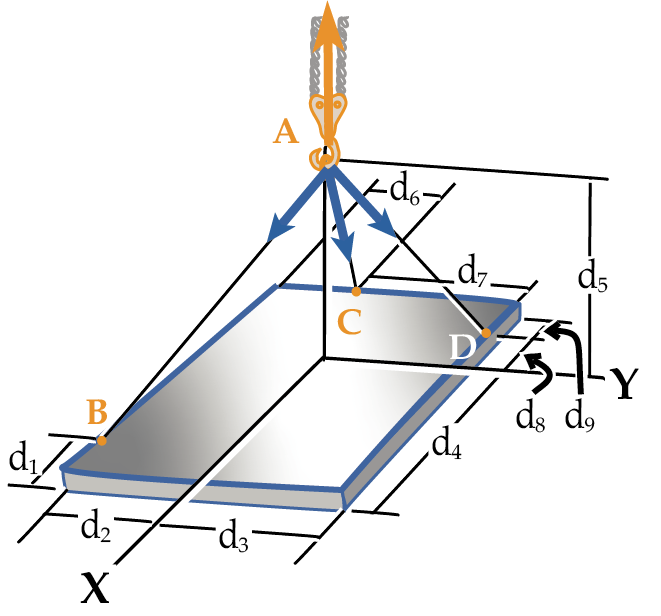

% Set up the distances
d_1 = 2;  % m
d_2 = 7;  % m
d_3 = 7;  % m
d_4 = 6;  % m
d_5 = 12; % m
d_6 = 2;  % m
d_7 = 10; % m
d_8 = 4;  % m
d_9 = 1;  % m

% Compute the mass here

First, define the points `A`, `B`, `C`, and `D`. You will also need to define the unit vectors in each relevant direction.

Define the symbolic tension in each cable: $T_{AB}$, $T_{AC}$ and $T_{AD}$. 

syms TAB TAC TAD  % N





Define a symbolic unknown to represent the weight we are trying to solve for. 

syms w    % N

Add up all the forces in each direction: `F_`x, `F_`y, `F_`z. 

F_x = 0 == 0;
F_y = 0 == 0;
F_z = 0 == 0;

Then use [`solve`](https://www.mathworks.com/help/symbolic/sym.solve.html) to find the values of `TAB`, `TAC`, and `TAD` in terms of `w`.

[TAB, TAC, TAD] = solve([F_x F_y F_z],[TAB TAC TAD])

Use `solve` again to determine the value of `w` that will result in a force of 15kN in each cable.

What is the maximum mass in kilograms that can be supported in this fashion without exceeding 15kN in any cable?

mass =  0;
CheckEx3(mass,d_1,d_2,d_3,d_4,d_5,d_6,d_7,d_8,d_9);

  **Try.**

- What happens to your answer in Exercise 3 if you change the geometry of the attachment points? 

- Is there a useful place to attach a third cable?

## Resources for further learning

- MATLAB Academy training: [Introduction to Symbolic Math with MATLAB](https://matlabacademy.mathworks.com/details/introduction-to-symbolic-math-with-matlab/symbolic)

- MATLAB Academy training: [Introduction to Linear Algebra with MATLAB](https://matlabacademy.mathworks.com/details/introduction-to-linear-algebra-with-matlab/linalg)

## References and Acknowledgements

Inspiration for this script came from work done by Professor [Orlando Arroyo](https://co.linkedin.com/in/orlando-arroyo-amell-9a68b151/en) of Universidad de La Sabana and conversations with Professor [Ricardo Parra Arango](https://co.linkedin.com/in/ricardo-l-parra-arango-661b0049). 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Glossary

**moment: **The effect of a force that causes rotation. In physics, you may see this referred to as a torque.

**Newton:** The SI unit of force, 1 Newton = 1 $\frac{\text{kg} \cdot \text{m}}{\text{s}^2}$. 

    This is the force needed to accelerate one kilogram of mass at the rate of one meter per second squared in the direction of the applied force.  

**resultant force:** The sum of all the forces in a system is the resultant force.

**unit vector:** A vector of length 1.

## Helper Functions

function checkDir(myAns)
if isstring(myAns)
    disp("This is the default. You can compute the direction.")
elseif myAns(1) ~= 0
    disp("Yes, it is in the x-direction, ")
    if myAns(1) > 0
        disp("but your sign is incorrect. Did you compute r x F or F x r?")
    else
        disp("and it is in the negative direction, away from us.")
        disp("This is will cause clockwise rotation around the x-axis.")
    end
elseif myAns(2) ~= 0
    disp("No, it is not in the y-direction. Please try again.")
elseif myAns(3) ~= 0
    disp("No, it is not in the z-direction. Please try again.")
else
    warning("How did you get here?")
end
end

function checkStaticF_B(F1,r1,F2,r2)
M = cross(r1,F1) + cross(r2,F2);
if all(M == zeros(size(F1)))
    disp("That is correct.")
elseif norm(M) < 1e-5
    disp("That appears to be rounded, can you be exact?")
else
    disp("The force at C is (" + M(1) + "," + M(2) + "," + M(3) + ").")
    if M(1) > 0 && M(2) == 0 && M(3) == 0
        disp("This indicates counter-clockwise rotation around C.")
    elseif M(1) < 0 && M(2) == 0 && M(3) == 0
        disp("This indicates clockwise rotation around C.")
    else
        disp("This is around the wrong axis entirely.")
    end
    disp("That is not a static equilibrium. Please try again.")
end
end

function GiveFeedbackEx1Coords(vec,val,str)
if isnan(vec)
    disp("This is the default value for " + str + ".")
elseif all(vec==val)
    disp("Yes, " + str + " = (" + vec(1) + "," + vec(2) + ","+vec(3)+") is correct.")
else
    disp("No, (" + vec(1) + "," + vec(2) + ","+vec(3)+") is incorrect as the vector representation of "+str+".")
end
end

function CheckEx1Coords(A,B,C)
    if any(isnan(A)) && any(isnan(B)) && any(isnan(C))
        disp("These are the default values for A, B, and C. Please complete the exercise.")
    else
       GiveFeedbackEx1Coords(A,[0 0 6],"A")
       GiveFeedbackEx1Coords(B,[0 2.5 0],"B")
       GiveFeedbackEx1Coords(C,[2 -3 0],"C")
    end
end

function out = CheckEx2(M)
    if M == 0
        disp("That is correct.")
        out = 1;
    elseif isnan(M)
        disp("That is the default value. Please complete the problem and resubmit.")
        out = -1;
    else
        disp("That is incorrect. Please try again.")
        out = 0;
    end
end

function out = CheckEx1(Mx,My,FC,FB,RO)
out = 0;
if any([isnan(Mx) isnan(My)])
    out = -1;
    disp("NaN is the default value. Please solve the problem and resubmit.")
else
    MR = cross(RO,FC+FB); % N-m
    sMx = dot(MR,[1 0 0]); % N-m
    sMy = dot(MR,[0 1 0]); % N-m

    if all([Mx == sMx  My == sMy])
        disp("You are correct.")
        out = 1;
    elseif Mx == sMx
        disp("You have a mistake in your calculations for My but Mx is correct.")
    elseif My == sMy
        disp("You have a mistake in your calculations for Mx but My is correct.")
    elseif length(Mx) ~= 1
        disp("The result should be a scalar value, not a vector.")
    else
        disp("Your answers are incorrect.")
    end
end
if out == 0
    disp("Please try again.")
end
end

function out = CheckEx3(myMass,d_1,d_2,d_3,d_4,d_5,d_6,d_7,d_8,d_9) %#ok<INUSD>
tol = 1e-2;
g = 9.81;
[num,den] = ComputeEx5(d_1,d_2,d_3,d_4,d_5,d_7,d_8,d_9);
out = 0;
if abs(myMass-num*1000/(den*g)) < tol
    disp("That is correct.")
    out = 1;
elseif abs(myMass-num/(den*g)) < tol
    disp("It looks like you are using metric tons, not kilograms.")
elseif abs(myMass - num*1000/den) < tol
    disp("It looks like you calcuated a weight in Newtons, not a mass in kilograms.")
elseif abs(myMass - num/den) < tol
    disp("It looks like you calculated a weight in kiloNewtons, not a mass in kilograms.")
elseif myMass == 0
    disp("This is the default value. Please solve this problem and resubmit.")
    out = -1;
elseif myMass < 0
    disp("You submitted a negative value for the mass. Does that make sense?")
else
    disp("This result is incorrect.")
end

if out == 0
    disp("Please correct your calcuation and resubmit.")
end
end

function [n,d] = ComputeEx5(d_1,d_2,d_3,d_4,d_5,d_7,d_8,d_9)
n=0;
d=1;
u_AB = [d_4-d_1,-d_2,-d_5]/norm([d_4-d_1,-d_2,-d_5]);
u_AC = [-(d_8+d_9),d_3-d_7,-d_5]/norm([-(d_8+d_9),d_3-d_7,-d_5]);
u_AD = [-d_8,d_3,-d_5]/norm([-d_8,d_3,-d_5]);

syms TAB TAC TAD w
T_AB = TAB*u_AB;
T_AC = TAC*u_AC;
T_AD = TAD*u_AD;

F_x = T_AB(1) + T_AC(1) + T_AD(1) == 0;
F_y = T_AB(2) + T_AC(2) + T_AD(2) == 0;
F_z = T_AB(3) + T_AC(3) + T_AD(3) + w == 0;

[TAB, TAC, TAD] = solve([F_x F_y F_z],[TAB TAC TAD]);
if double(subs(TAC,w,1)) == 0
    w1 = solve(TAB == 15,w);    % kN
    w2 = solve(TAD == 15,w);
    if double(w1)~=double(w2)
        warning("Unbalanced result.")
        MinWt = min(w1,w2);
        [n,d] = numden(MinWt);
    else
        [n,d] = numden(w1);
    end   
elseif double(subs(TAC,w,1)) > 0
    w1 = solve(TAB == 15,w);    % kN
    w2 = solve(TAD == 15,w);
    w3 = solve(TAC == 15,w);
    MinWt = min([w1,w2,w3]);
    [n,d] = numden(MinWt);
else
    warning("Unexpected result. The tension in cable C is negative!")
end
end